clear all
syms pi q1 q2 dq1 dq2 ddq1 ddq2 l1 s l2 l m1 m2 I1 I2 g real

l1 = s

$$l1 = s$$

O0 = [0 0 0]'

O0 =      0
     0
     0


Oc1 = [0 0 0]'

Oc1 =      0
     0
     0


O1 = [l1*cos(q1) l1*sin(q1) 0]'

$$O1 = \left(\begin{array}{c} s\,\cos\left(q_{1}\right)\\ s\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

Oc2 = [(q2+l1)*cos(q1) (q2+l1)*sin(q1) 0]'

$$Oc2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(q_{2}+s\right)\\ \sin\left(q_{1}\right)\,\left(q_{2}+s\right)\\ 0 \end{array}\right)$$

Need for Z1

(Rz(q1)*Tx(l1))

Undefined function 'Rz' for input arguments of type 'sym'.


Z0 = [0 0 1]'

Z0 =      0
     0
     1


Z1 = [cos(q1) sin(q1) 0]'

$$Z1 = \left(\begin{array}{c} \cos\left(q_{1}\right)\\ \sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

jacobians

Zer = [0 0 0]';
Jv1 = [cross(Z0,(Oc1-O0)), Zer]

Jv1 =      0     0
     0     0
     0     0


Jv2 = [cross(Z0,(Oc2-O0)), Z1]

$$Jv2 = \left(\begin{array}{cc} -\sin\left(q_{1}\right)\,\left(q_{2}+s\right) & \cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\left(q_{2}+s\right) & \sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

Jw1 = [Z0, Zer]

Jw1 =      0     0
     0     0
     1     0


Jw2 = [Z0, Zer]

Jw2 =      0     0
     0     0
     1     0


Kinetic energy

R1 = [
 cos(q1) -sin(q1) 0
 sin(q1) cos(q1) 0
 0 0 1]

$$R1 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R2 = R1

$$R2 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

q = [q1;q2];
D1 = m1*Jv1'*Jv1 + Jw1'*R1*I1*R1'*Jw1

$$D1 = \left(\begin{array}{cc} I_{1} & 0\\ 0 & 0 \end{array}\right)$$

D2 = simplify(m2*Jv2'*Jv2 + Jw2'*R2*I2*R2'*Jw2)

$$D2 = \left(\begin{array}{cc} m_{2}\,{q_{2}}^{2}+2\,m_{2}\,q_{2}\,s+m_{2}\,s^{2}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

D=D1+D2;
D=simplify(D)

$$D = \left(\begin{array}{cc} m_{2}\,{q_{2}}^{2}+2\,m_{2}\,q_{2}\,s+m_{2}\,s^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

P1 = m1*g*0;
P2 = m2*g*((q2+l1)*sin(q1));
P = P1+P2

$$P = g\,m_{2}\,\sin\left(q_{1}\right)\,\left(q_{2}+s\right)$$

G1 = diff(P, q1)

$$G1 = g\,m_{2}\,\cos\left(q_{1}\right)\,\left(q_{2}+s\right)$$

G2 = diff(P,q2)

$$G2 = g\,m_{2}\,\sin\left(q_{1}\right)$$

G = [G1; G2]

$$G = \left(\begin{array}{c} g\,m_{2}\,\cos\left(q_{1}\right)\,\left(q_{2}+s\right)\\ g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

dq = [dq1; dq2];
ddq = [ddq1; ddq2];
C = Coriolis(D,q,dq,2);
C=simplify(C)

$$C = \left(\begin{array}{cc} {\mathrm{dq}}_{2}\,m_{2}\,\left(q_{2}+s\right) & {\mathrm{dq}}_{1}\,m_{2}\,\left(q_{2}+s\right)\\ -{\mathrm{dq}}_{1}\,m_{2}\,\left(q_{2}+s\right) & 0 \end{array}\right)$$

Dynamic equation in matrix form:

tor = D*ddq+C*dq+G

$$tor = \left(\begin{array}{c} {\mathrm{ddq}}_{1}\,\left(m_{2}\,{q_{2}}^{2}+2\,m_{2}\,q_{2}\,s+m_{2}\,s^{2}+I_{1}+I_{2}\right)+g\,m_{2}\,\cos\left(q_{1}\right)\,\left(q_{2}+s\right)+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,m_{2}\,\left(q_{2}+s\right)\\ -m_{2}\,\left(q_{2}+s\right)\,{{\mathrm{dq}}_{1}}^{2}+{\mathrm{ddq}}_{2}\,m_{2}+g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

D_func(q1,q2) = subs(D,{m1, m2, I1, I2, l1, g},{2 2 1 2 0.2 9.81});
C_func(q1,q2,dq1,dq2) = subs(C*dq ,{m1, m2, I1, I2, l1, g},{2 2 1 2 0.2 9.81});
G_func(q1,q2) = subs(G ,{m1, m2, I1, I2, l1, g},{2 2 1 2 0.2 9.81});

D_func(0,0)    

$$ans = \left(\begin{array}{cc} \frac{77}{25} & 0\\ 0 & 2 \end{array}\right)$$

C_func(0,0,0,0)

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

G_func(0,0)

$$ans = \left(\begin{array}{c} \frac{981}{250}\\ 0 \end{array}\right)$$

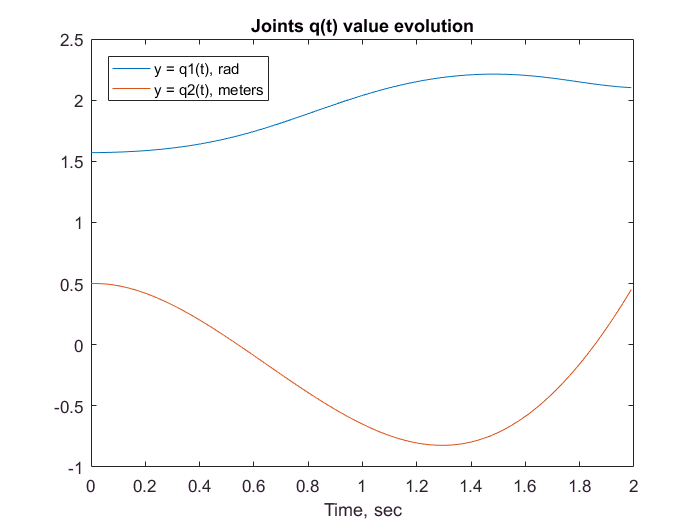

q1_0 = pi/2;
q2_0 = 0.5;
dq1_0 = 0;
dq2_0 = 0.1;
dt = 0.01;
U = [3; 9.0];
dU = [0; 19.07];
ddU = [-2; -9.95];
n=200;

q1p = [];
q2p = [];
dq1p = [];
dq2p = [];
ddq1p = [];
ddq2p = [];
u1p = [];
u2p = [];

for i = 1:n
 q1p(i)=q1_0;
 q2p(i)=q2_0;
 u1p(i)=U(1);
 u2p(i)=U(2);
 dq1p(i)=dq1_0;
 dq2p(i)=dq2_0;
 
 ddq = inv(D_func(q1_0, q2_0))*(U-C_func(q1_0, q2_0,dq1_0,dq2_0)-G_func(q1_0,q2_0));
 
 ddq1p(i) = ddq(1);
 ddq2p(i) = ddq(2);
 
 dq1_0=dq1p(i) + double(ddq(1)*dt);
 dq2_0=dq2p(i) + double(ddq(2)*dt);

 q1_0 = q1p(i) + dq1_0*dt;
 q2_0 = q2p(i) + dq2_0*dt;
 U = U + dU * dt;
 dU = dU + ddU * dt;
end

t = 0:dt:(dt*(n-1));
figure
plot(t,q1p, t,q2p)
title('Joints q(t) value evolution')
xlabel('Time, sec') 
legend({'y = q1(t), rad','y = q2(t), meters'},'Location','northwest')

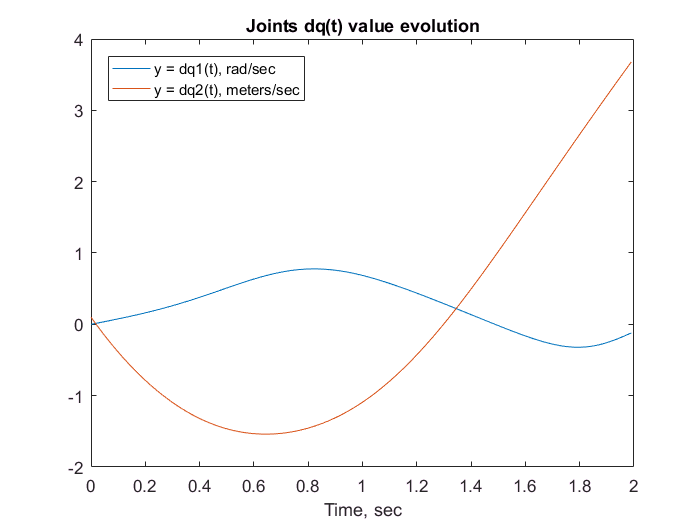

t = 0:dt:(dt*(n-1));
figure
plot(t,dq1p, t,dq2p)
title('Joints dq(t) value evolution')
xlabel('Time, sec') 
legend({'y = dq1(t), rad/sec','y = dq2(t), meters/sec'},'Location','northwest')

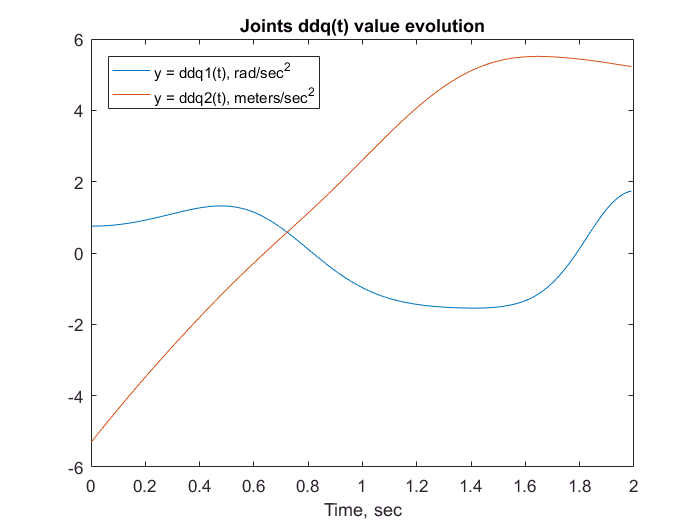

t = 0:dt:(dt*(n-1));
figure
plot(t,ddq1p, t,ddq2p)
title('Joints ddq(t) value evolution')
xlabel('Time, sec') 
legend({'y = ddq1(t), rad/sec^2','y = ddq2(t), meters/sec^2'},'Location','northwest')

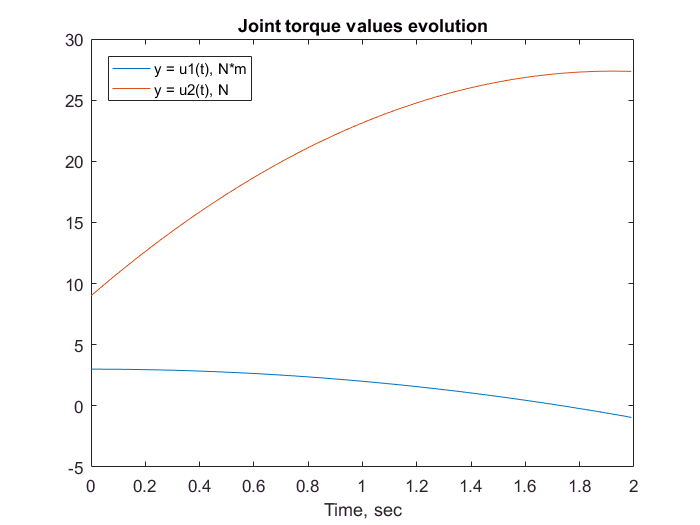

t = 0:dt:(dt*(n-1));
figure
plot(t,u1p, t,u2p)
title('Joint torque values evolution')
xlabel('Time, sec') 
legend({'y = u1(t), N*m','y = u2(t), N'},'Location','northwest')